clc
clear
close all
rng('default');

set(0, 'defaultAxesFontSize', 12)
set(0, 'DefaultLineLineWidth', 2);
set(0, 'defaultAxesFontSize', 14)
set(0, 'defaultAxesTickLabelInterpreter','latex');
set(0, 'defaultlegendInterpreter','latex')

## Generate data

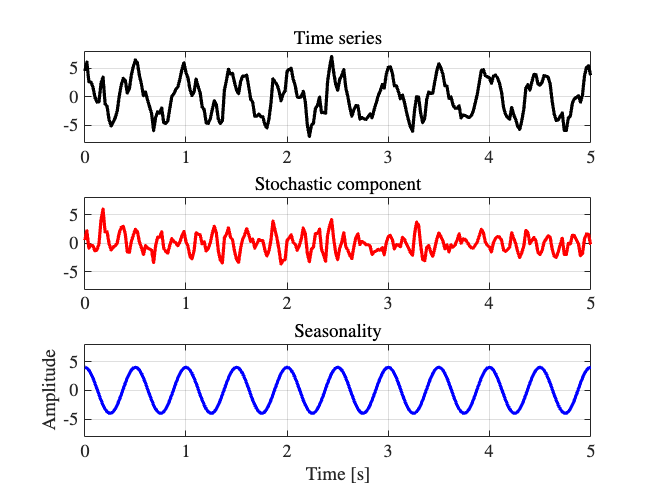

me = 0; % mean of the white noise
N = 11000; % number of data
e = randn(N, 1) + me; % generate WN vector
y = zeros(length(e), 1); % initialize output vector
y_rec = zeros(length(e), 1); % initialize output vector computed with explicit recursive form
Ts = 0.02; % sample time [s]
fs = 1/Ts; % sampling frequency [Hz]
time = (0:Ts:(N*Ts)-Ts)';

% Transfer function of the process
a = [0.7 -0.2 -0.3]; % coefficients of the AR part
Hz = tf([1 0 0 0], [1 -a] ,'Ts', Ts, 'variable', 'z^-1');


C = cell2mat(Hz.Numerator); % coefficients numerator
A = cell2mat(Hz.Denominator); % coefficients denominator

v = filter(C, A, e); % generate output data with filter command


% Add stagionality to the process
freq_season = 2; % [Hz]
period_season = 1/freq_season; % [s]
amp_season = 4;
seasonality = amp_season * cos(2*pi * freq_season*time);
y = v + seasonality;


figure
h1 = subplot(311);
plot(time, y, 'k', 'linewidth', 2);
xlim([0, 5]); ylim([-8, 8]); grid on;
title('Time series', 'interpreter', 'latex');
h2 = subplot(312);
plot(time, v, 'r', 'linewidth', 2);
xlim([0, 5]); ylim([-8, 8]); grid on;
title('Stochastic component', 'interpreter', 'latex');
h3 = subplot(313);
plot(time, seasonality, 'b', 'linewidth', 2);
xlim([0, 5]); ylim([-8, 8]); grid on;
title('Seasonality', 'interpreter', 'latex');
xlabel('Time [s]', 'interpreter', 'latex'); ylabel('Amplitude', 'interpreter', 'latex')

## Pre-process data

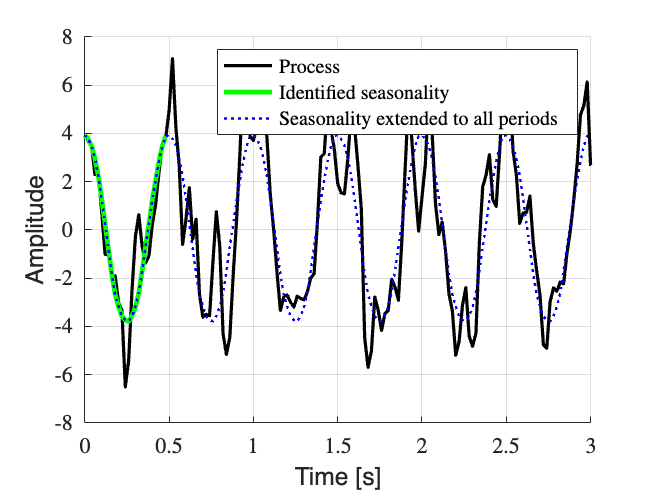

% Remove initial condition to obtain a stationary process
Ninit = 1000;
y = y(Ninit+1:end);
e = e(Ninit+1:end);
v = v(Ninit+1:end);
N = N - Ninit;
time = (0:Ts:(N*Ts)-Ts)';


% Identify the seasonality on one period, assuming that the periodicity
% is known (e.g. estimated by looking at the data)
N_season = period_season*fs; % number of data in the seasonality
seasonality_hat = zeros(N_season, 1); % estimated seasonality
for t = 1 : 1 : N_season
    % take values at time instants multiples of period_season and average them
    seasonality_hat(t) = mean( y(t:N_season:(t+N_season*round(N/N_season)-1) ));
end

S_hat = seasonality_hat; % extended estimated seasonality
% Extend the estimated seasonality all over the data
for k = 1 : 1 : round(N/N_season)-1
    S_hat = [S_hat; seasonality_hat];
end


figure
hold all
plot(time, y, 'k' ,'linewidth', 2);
plot(time(1:N_season), seasonality_hat, 'g' ,'linewidth', 3);
plot(time, S_hat, 'b:' ,'linewidth', 1.5);
grid on; xlabel('Time [s]'); ylabel('Amplitude');
legend('Process', 'Identified seasonality', 'Seasonality extended to all periods');
xlim([0, 3]);

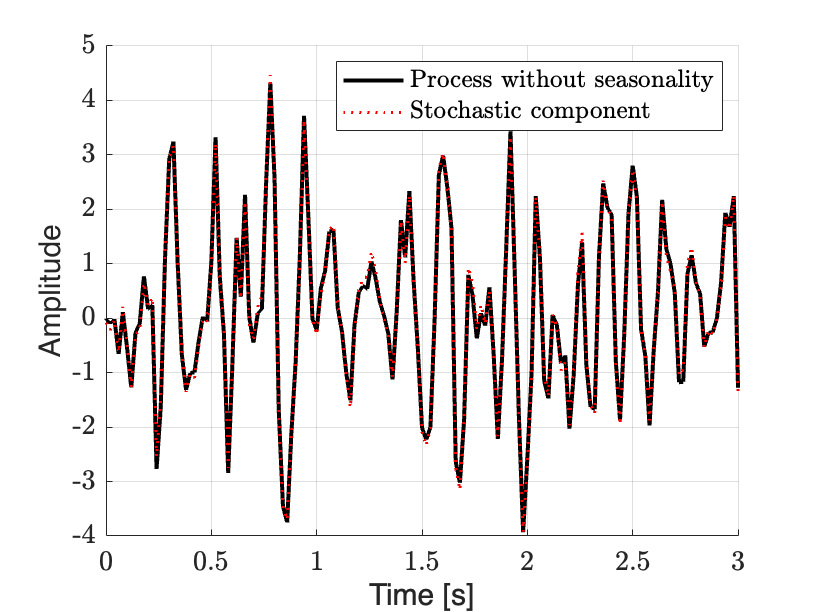



% Remove estimated seasonality
ys = y - S_hat;

figure
hold all
plot(time, ys, 'k' ,'linewidth', 2);
plot(time, v, 'r:' ,'linewidth', 1.5);
grid on; xlabel('Time [s]'); ylabel('Amplitude');
legend('Process without seasonality', 'Stochastic component');
xlim([0, 3]);

## Estimate the autocovariance function of y(t)

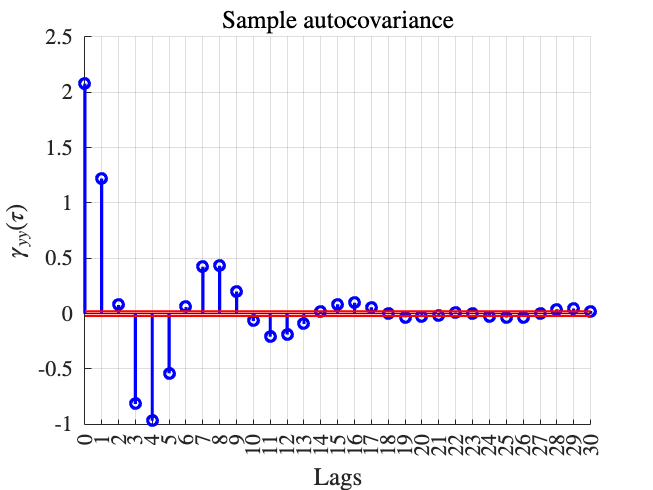

lags = 30; % lags up to which compute the estimated autocovariance function
[Ryy_hat, ~, bounds] = autocorr(ys, lags); % sample autocorrelation function
% - bounds contains the 95% confidence intervals on the estimate


gammayy_hat_0 = var(ys); % variance of y(t)
gammayy_hat = gammayy_hat_0 * Ryy_hat;

figure
hold on
stem(0:1:lags, gammayy_hat, 'b', 'linewidth', 2);
l = line([0 lags], [bounds(1) bounds(1)]); l.LineStyle = '-'; l.LineWidth = 1.5; l.Color = 'r';
l = line([0 lags], [bounds(2) bounds(2)]); l.LineStyle = '-'; l.LineWidth = 1.5; l.Color = 'r';
grid on; xlabel('Lags', 'interpreter', 'latex');  ylabel('$\gamma_{yy}(\tau)$', 'interpreter', 'latex')
title('Sample autocovariance', 'interpreter', 'latex');
xticks(0:1:lags);

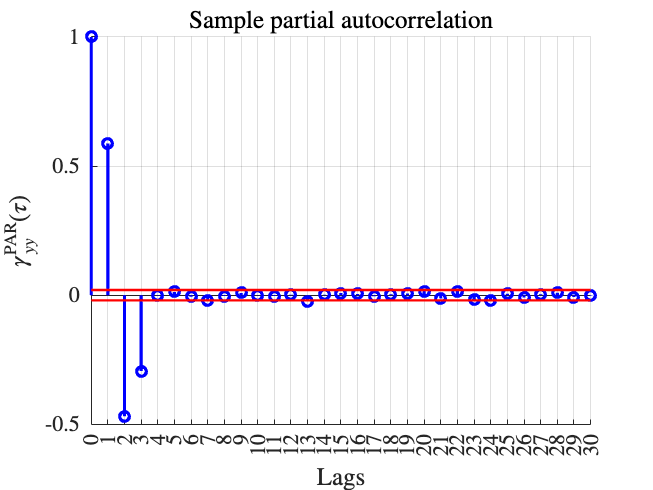




% Partial autocorrelation function
[gammayy_PAR_hat, ~, bounds] = parcorr(ys, lags);

figure
hold on
stem(0:1:lags, gammayy_PAR_hat, 'b', 'linewidth', 2);
l = line([0 lags], [bounds(1) bounds(1)]); l.LineStyle = '-'; l.LineWidth = 1.5; l.Color = 'r';
l = line([0 lags], [bounds(2) bounds(2)]); l.LineStyle = '-'; l.LineWidth = 1.5; l.Color = 'r';
grid on; xlabel('Lags', 'interpreter', 'latex'); ylabel('$\gamma^\textrm{PAR}_{yy}(\tau)$', 'interpreter', 'latex')
title('Sample partial autocorrelation', 'interpreter', 'latex');
xticks(0:1:lags);

## Identify a model of the time series

N_ident = round(N/2);
N_valid = N - N_ident;

data = iddata(ys, e, Ts);
data_ident = iddata(ys(1:N_ident), [], Ts); % create identification data object
data_valid = iddata(ys(N_valid + 1:end), [], Ts); % create identification data object

% Identify an AR(na) model
na = 3;
model = ar(data_ident.OutputData, na, 'Ts', Ts); % uso un modello AR(3)
present(model)

                                                                                                                                                                                                                                                                                                        
model =                                                                                                                                                                                                                                                                                                 
Discrete-time AR model: A(z)y(t) = e(t)                                                                                                                                                                                                                                                                 
  A(z) = 1 - 0.7171 (+/- 0.01356) z^-1 + 0.223 (+/- 0.01664) z^-2 + 0.2852 (+/- 0.01356) z^-3                

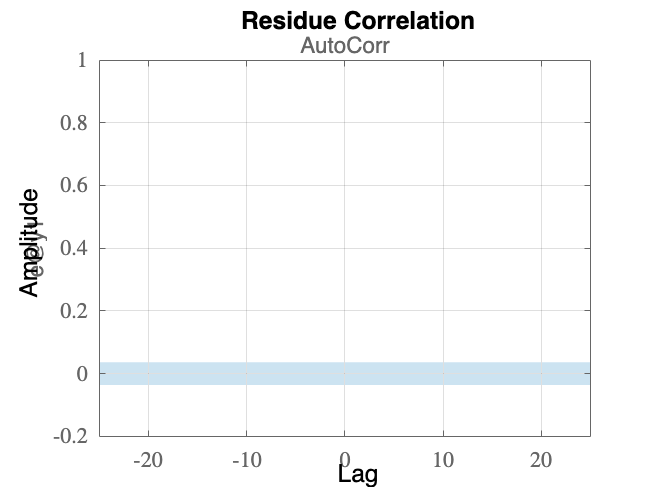


% Compute the prediction error: if it is a white noise, we have chosen the
% rigth model
figure;
resid(model, data_valid); grid on;
set(findall(gcf,'type','line'), 'linewidth', 2)

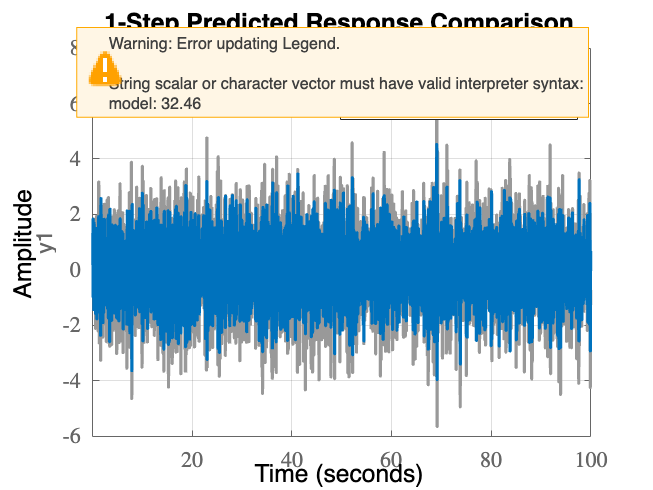


figure;
compare(model, data_valid, 1); % 1-step prediction comparison
set(findall(gcf,'type','line'), 'linewidth', 2); grid on;



% Un modello dinamico è buono quando il predittore ad un passo è un rumore
% bianco
% Prediction on validation data
k = 1; % prediction horizon
y_hat_pred = predict(model, data_valid, k); % predict
y_hat = y_hat_pred.OutputData; % get predicted data

time_val = 0:Ts:(N_valid)*Ts-Ts;
figure
hold all
plot(time_val, y_hat, 'b', 'linewidth', 2);
plot(time_val, data_valid.OutputData, 'k--', 'linewidth', 2);
legend('1-step prediction', 'True data')
xlim([0, 3]);
grid on;
ylim([-5, 5]);
xlabel('Time [s]'); ylabel('Amplitude');



ESR = var(data_valid.OutputData - y_hat) / var(data_valid.OutputData - 0);
fprintf('Reduced the prediction uncertainty of %.2f percent', (1 - ESR) * 100); fprintf('\n');

Reduced the prediction uncertainty of 54.39 percent


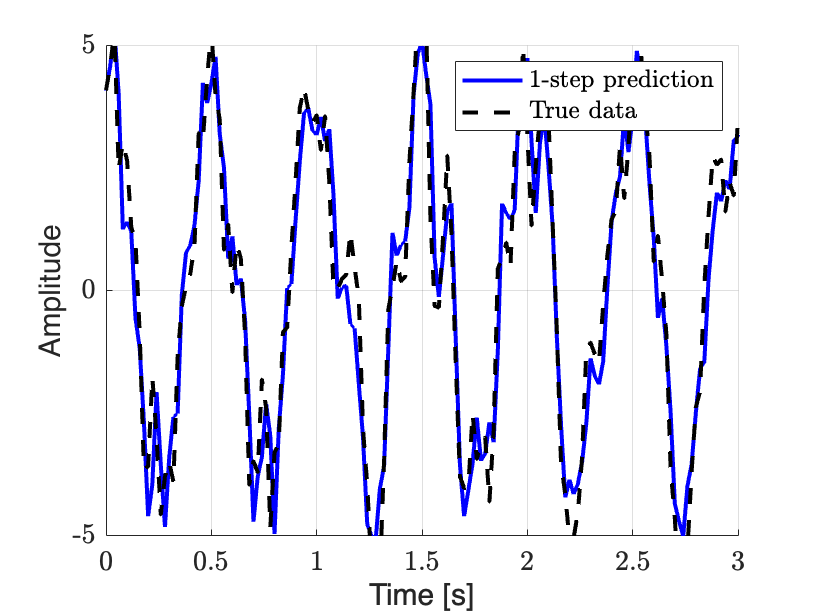



% Prediction on original validation data
time_val = 0:Ts:(N_valid)*Ts-Ts;
y_val = y(N_valid + 1:end);

y_hat_s = y_hat + S_hat(N_valid + 1:end);

figure
hold all
plot(time_val, y_hat_s, 'b', 'linewidth', 2);
plot(time_val, y_val, 'k--', 'linewidth', 2);
legend('1-step prediction', 'True data')
xlim([0, 3]);
grid on;
ylim([-5, 5]);
xlabel('Time [s]'); ylabel('Amplitude');

## Forecast

% Identify on all the data
model = ar(data.OutputData, na, 'Ts', Ts); % uso un modello AR(3)

present(model)

                                                                                                                                                                                                                                                                                                        
model =                                                                                                                                                                                                                                                                                                 
Discrete-time AR model: A(z)y(t) = e(t)                                                                                                                                                                                                                                                                 
  A(z) = 1 - 0.7253 (+/- 0.009561) z^-1 + 0.2157 (+/- 0.01181) z^-2 + 0.2935 (+/- 0.009563) z^-3             


% Forecast the next k values
k = 20;
y_hat_fore = forecast(model, data, k);
y_hat = y_hat_fore.OutputData;

time_fore = time(end) + [Ts:Ts:(k*Ts)]';
time_all = [time; time(end) + [Ts:Ts:(k*Ts)]'];
figure;
hold all
plot(time_fore, y_hat, 'b', 'linewidth', 2);
plot(time_all, [y; y_hat(1); nan*zeros(k-1, 1)], 'k--');
grid on;
xlim([199, 201]);
legend(['k = ' int2str(k), '-step forecast'], 'True data');
xlabel('Samples [-]'); ylabel('Amplitude');